# Convolución discreta 

## **Materia:**

Señales y sistemas

## **Elaborado por:**

Gael Jovani López García 1191699

Diego Bejarano Bedolla 11y nose

## **Maestro:**

Jorge Eduardo Ibarra Esquer

## **Introducción**

La convolución discreta es utilizada para combinar dos señales discretas y obtener una tercera señal donde esta señal es a partir de la misma combinación de estas dos. Esta operación permite analizar cómo la forma de una señal se ve afectada al pasar por un sistema lineal e invariante en el tiempo(LTI, por sus siglas en inglés).

Esta está compuesta por una señal de entrada y la señal de salida, donde para poder entender la convolución y su modelo matemático, necesitamos saber como funciona.

Básicamente intentamos recorrer una señal de entrada a la señal de salida del sistema, causando por lógica un "traslape" entre las dos funciones, donde el cálculo de la señal respuesta de la convolución se ve definida por la la suma de multiplicacion/es de cada traslape de las dos señales, como es un recorrido se hace ese cálculo por cada instante de la longitud de la señal resultante, que para saber la longitud, se explicará mas adelante.

**Modelo matemático de la convolución discreta:**

## 
$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack *h\left\lbrack n-k\right\rbrack$$


**Donde:**

$x\left\lbrack k\right\rbrack$: La señal de entrada

$h\left\lbrack n-k\right\rbrack$: Es la segunda señal invertida y desplazada (La respuesta al impulso del sistema)

$y\left\lbrack n\right\rbrack$: La señal resultado

Ademas cabe aclarar que la longitud final de la señal resultado se determina con:

## 
$$\textrm{Longitud}\;\textrm{de}\;y\left\lbrack n\right\rbrack =\textrm{Lx}+\textrm{Lh}-1$$


Ahora teniendo en cuenta las nuevas definiciones, cuando se haga una convolución se necesita desplazar e invertir una señal de las dos, que en tal caso podemos seleccionar cualquiera de las dos, entonces viene definido que, la señal $x\left\lbrack k\right\rbrack$ traslapa o recorra la función invertida $h\left\lbrack n-k\right\rbrack$ y que su resultado será $y\left\lbrack n\right\rbrack$, donde la longitud ya se definió como $\textrm{Lx}+\textrm{Lh}-1$.

Para dar más seguimiento en la convolución discreta, se dispondrá de pequeños ejemplo:

**Ejemplos**

**Funciones presentadas:**


$$\begin{array}{l}
x_1 \left\lbrack n\right\rbrack =\left\lbrace 1,0,0,0,0\right\rbrace \\
x_2 \left\lbrack n\right\rbrack =\left\lbrace 1,1,1,1,1\right\rbrace \\
x_3 \left\lbrack n\right\rbrack =\left\lbrace 1,2,3,2,1\right\rbrace \\
x_4 \left\lbrack n\right\rbrack =\left\lbrace 1,0\ldotp 5,0\ldotp 25,0\ldotp 125,0\ldotp 0625\right\rbrace 
\end{array}$$


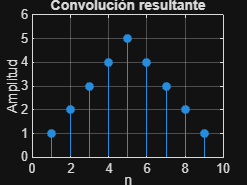

%Función de entrada
x1 = [1,1,1,1,1];

%Segunda Función
h1 = [1,1,1,1,1];

%Convolución resultante
y = conv(x1,h1);
l = max(y);
figure;
stem(y,'filled');
title('Convolución resultante');
grid on
ylim([0 l+1]);
xlabel('n');
ylabel('Amplitud');

Ya que hemos definido que es la convolución discreta y ademas hemos visto algunos ejemplos ahora hablaremos de las aplicaciones reales de estas operaciones. Entre sus aplicaciones las más destacadas son el procesamiento de señales, sistemas de control, visión por computadora, procesamiento de imagenes y en algunos campos como las matemáticas y la física.

Cada una responde a la respuesta de eventos de un sistema como los mencionados son, modelos matemáticos, cpu, algoritmos entre otros. 

## Representación de una señal discreta como combinaciones de impulsos unitarios

Como se menciona en el subititulo, se puede representar una señal discreta como una combinación de impulsos unitarios, pero primero, es importante mencionar el comportamiento de un impulso unitario:

## 
$$\delta \left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1, & \textrm{si}\;n=0\\
0, & \textrm{sí}\;n\not= 0
\end{array}\right.$$


Cualquier señal discreta se puede representar como un impulsos unitarios desplazados en el tiempo, donde cada desplazamiento corresponde a un termino de la señal y está ponderado por el valor de la señal en ese instante. Esto se puede representar como:

## 
$$x\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack *\delta \left\lbrack n-k\right\rbrack$$


**Donde:**

$x\left\lbrack k\right\rbrack$: Es la entrada en el instante K.

$\delta \left\lbrack n-k\right\rbrack$: Es el pulso unitario desplazado.

La suma recorre todos los valores posibles de $k$, colocando un impulso unitario en cada posición y escalandolo por el valor $x\left\lbrack k\right\rbrack$.

**Ejemplo:**

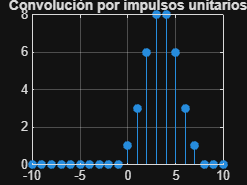

n = -5:5;
%Recorrer la convolución
z =0;

%Pulso unitario
delta_n = @(n) double(n == z);        

%Señal impulso [1,2,3,2,1]
x = delta_n(n) + 2*delta_n(n-1) + 3*delta_n(n-2) + 2*delta_n(n-3) + delta_n(n-4);

%Segunda señal impulso [1,1,1,1]
h = delta_n(n) + delta_n(n-1) + delta_n(n-2) + delta_n(n-3);


%Nuevo rango de convolución
n_conv = (min(n)+min(n)):(max(n)+max(n));

%Convolución resultante
stem(n_conv, conv(x, h), 'filled');
title('Convolución por impulsos unitarios');
xlabel('n');
ylabel('Amplitud');
grid on;

## Sumatoria de convolución a partir de la respuesta al impulso del sistema

Para calcular $y\left\lbrack n\right\rbrack$ se debe hacer la sumatoria del desplazamiento de la señal $h\left\lbrack k\right\rbrack$ por $n$ unidades y multiplicarlos por los valores correspondientes de $x\left\lbrack k\right\rbrack$, primero haremos un cambio de variable de $x\left\lbrack n\right\rbrack \;$a $x\left\lbrack k\right\rbrack$  y  $h\left\lbrack n\right\rbrack \;$a $h\left\lbrack k\right\rbrack$, despues de todo esto ahora podemos aplicar la formula la cual quedaría de la siguiente manera. 

## 
$$y\left\lbrack n\right\rbrack =\sum_{k=-\infty }^{\infty } x\left\lbrack k\right\rbrack *h\left\lbrack n-k\right\rbrack$$


Comprendiendo que la longitud máxima es la suma de las longitudes de las dos funciones menos 1


$$n_{\textrm{maximo}} =L_x +L_h -1$$


sumamos por cada instante de cada señal:

$x\left\lbrack k\right\rbrack$ * $h\left\lbrack n-k\right\rbrack$ = $y\left\lbrack n\right\rbrack$

donde $k$ es el instante de tiempo actual de la señal

donde $n$ es el instante del tiempo actual de la función convolucionada

La suma de las multiplicaciones de la convoluión en el instante de n terminará hasta que k(instante de las señales) en las dos señales termine.

Por ejemplo si las dos señales tienen una longitud de 2, y su n maximo es igual 3, el desarrollo

matematico sería:

$n$ = 0

$x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 0-0\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 0-1\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$y\left\lbrack 0\right\rbrack$ = $x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 0-0\right\rbrack$ + $x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 0-1\right\rbrack$

$n$ = 1

$x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 1-0\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 1-1\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$y\left\lbrack 1\right\rbrack$ = $x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 1-0\right\rbrack$ + $x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 1-1\right\rbrack$

$n$ = 2

$x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 2-0\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 2-1\right\rbrack$ = $y\left\lbrack 0\right\rbrack$

$y\left\lbrack 2\right\rbrack$ = $x\left\lbrack 0\right\rbrack$ * $h\left\lbrack 2-0\right\rbrack$ + $x\left\lbrack 1\right\rbrack$ * $h\left\lbrack 2-1\right\rbrack$

La señal convolucionada sería:

$y$ = $\left\lbrace y\left\lbrack 0\right\rbrack ,y\left\lbrack 1\right\rbrack ,y\left\lbrack 2\right\rbrack \right\rbrace$

Otra cosa importante a señalar y es que las señales que en cierto instante no tienen ningún valor, se sobreentiende que es cero.

**Ejemplo de procedimiento para el cálculo de una convolución discreta: **

Tomando como ejemplo las siguientes señales:


$$x\left\lbrack n\right\rbrack =\left\lbrace 1,2,3\right\rbrace$$



$$h\left\lbrack n\right\rbrack =\left\lbrace 2,-1,3\right\rbrace \;$$


donde $h\left\lbrack n\right\rbrack$ será la función desplazada y invertida

Para $n=0$ 


$$y\left\lbrack 0\right\rbrack =x\left\lbrack 0\right\rbrack *h\left\lbrack 0\right\rbrack \to x\left\lbrack 0\right\rbrack =1,\;h\left\lbrack 0\right\rbrack =2$$



$$y\left\lbrack 0\right\rbrack =x\left\lbrack 1\right\rbrack *h\left\lbrack -1\right\rbrack \to x\left\lbrack 1\right\rbrack =2,\;h\left\lbrack -1\right\rbrack =0$$



$$y\left\lbrack 0\right\rbrack =x\left\lbrack 2\right\rbrack *h\left\lbrack -2\right\rbrack \to x\left\lbrack 2\right\rbrack =3,\;h\left\lbrack -2\right\rbrack =0$$



$$y\left\lbrack 0\right\rbrack =1*2=2$$


Para $n=1$


$$y\left\lbrack 1\right\rbrack =x\left\lbrack 0\right\rbrack *h\left\lbrack 1\right\rbrack \to x\left\lbrack 0\right\rbrack =1,\;h\left\lbrack 1\right\rbrack =-1$$



$$y\left\lbrack 1\right\rbrack =x\left\lbrack 1\right\rbrack *h\left\lbrack 0\right\rbrack \to x\left\lbrack 1\right\rbrack =2,\;h\left\lbrack 0\right\rbrack =2$$



$$y\left\lbrack 1\right\rbrack =x\left\lbrack 2\right\rbrack *h\left\lbrack -1\right\rbrack \to x\left\lbrack 2\right\rbrack =3,\;h\left\lbrack -1\right\rbrack =0$$



$$y\left\lbrack 1\right\rbrack =1*-2+2*2=3$$


Para $n=2$ 


$$y\left\lbrack 2\right\rbrack =x\left\lbrack 0\right\rbrack *h\left\lbrack 2\right\rbrack \to x\left\lbrack 0\right\rbrack =1,\;h\left\lbrack 2\right\rbrack =3$$



$$y\left\lbrack 2\right\rbrack =x\left\lbrack 1\right\rbrack *h\left\lbrack 1\right\rbrack \to x\left\lbrack 1\right\rbrack =2,\;h\left\lbrack 1\right\rbrack =-1$$



$$y\left\lbrack 2\right\rbrack =x\left\lbrack 2\right\rbrack *h\left\lbrack 0\right\rbrack \to x\left\lbrack 2\right\rbrack =3,\;h\left\lbrack 0\right\rbrack =2$$



$$y\left\lbrack 2\right\rbrack =1*3+2*-1+3*2=7$$


Para $n=3$


$$y\left\lbrack 3\right\rbrack =x\left\lbrack 0\right\rbrack *h\left\lbrack 3\right\rbrack \to x\left\lbrack 0\right\rbrack =1,\;h\left\lbrack 3\right\rbrack =0$$



$$y\left\lbrack 3\right\rbrack =x\left\lbrack 1\right\rbrack *h\left\lbrack 2\right\rbrack \to x\left\lbrack 1\right\rbrack =2,\;h\left\lbrack 1\right\rbrack =3$$



$$y\left\lbrack 3\right\rbrack =x\left\lbrack 2\right\rbrack *h\left\lbrack 1\right\rbrack \to x\left\lbrack 2\right\rbrack =3,\;h\left\lbrack 2\right\rbrack =-1$$



$$y\left\lbrack 3\right\rbrack =2*3+3*-1=3$$


Para $n=4$


$$y\left\lbrack 4\right\rbrack =x\left\lbrack 0\right\rbrack *h\left\lbrack 4\right\rbrack \to x\left\lbrack 0\right\rbrack =1,\;h\left\lbrack 4\right\rbrack =0$$



$$y\left\lbrack 4\right\rbrack =x\left\lbrack 1\right\rbrack *h\left\lbrack 3\right\rbrack \to x\left\lbrack 1\right\rbrack =2,\;h\left\lbrack 3\right\rbrack =0$$



$$y\left\lbrack 4\right\rbrack =x\left\lbrack 2\right\rbrack *h\left\lbrack 2\right\rbrack \to x\left\lbrack 2\right\rbrack =3,\;h\left\lbrack 2\right\rbrack =3$$



$$y\left\lbrack 4\right\rbrack =3*3=9$$


Entonces $y$[n] es igual a :


$$y\left\lbrack n\right\rbrack =\left\lbrace 2,3,7,3,9\right\rbrace$$


Para poder ver el resultado final de estas dos señales, las podemos indicar en los siguientes incisos o en tal caso que se quiera elegir otro también lo hay.

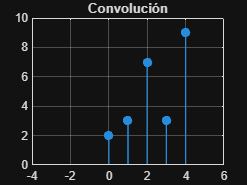

x = [1,2,3];

h = [2,-1,3];

%Primero se determina las longitud de las señales
Lx = length(x); 
Lh = length(h);

%Luego la longitud de la señal resultante de la convolución discreta, longitud de y[n] 
Ly = Lx + Lh - 1; 

%Se crea en este caso la "señal" resultante de la convolución donde
%primeramente son con ceros pero es por que se alamcenarán en la señal los
%datos correspondientes
y = zeros(1, Ly);

%y[n] = sum x[k] * h[n-k]
%Cabe señalar que los ciclos de abajo son una implementación de convolución
%discreta propuesto
for n = 0:Ly
    for k = 1:Lx
        if (n-k+1 > 0) && (n-k+1 <= Lh) 
            y(n) = y(n) + x(k) * h(n-k+1);
        end
    end
end

%Determinar la variable del tiempo para la señal, que en este caso
%simplemente es la longitud de la señal convolucionada en un vector
n_y = 0:Ly-1; 
len = length(y);

stem(n_y, y, 'filled', 'LineWidth',1);
title('Convolución');
xlim([-len+1 len+1]);
xlabel('n');
ylabel('Amplitud');
grid on;

## Cálculo de una convolución

**Ejemplos propuestos**


$$\begin{array}{l}
x\left\lbrack n\right\rbrack =\left\lbrace 1,1,1,1,\right\rbrace \\
h\left\lbrack n\right\rbrack =\left\lbrace 0,1,3,2,1\right\rbrace 
\end{array}$$


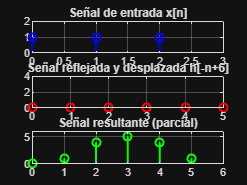

% Señales de entrada
x2 = [1, 1, 1];  % Señal x[n]
h2 = [0, 1, 3, 1];  % Señal h[n]

% Calcular la longitud de la señal resultante
longitud_y2 = length(x2) + length(h2) - 1;

% Reflejar la señal h[n] para obtener h[-n]
h2_invertida = fliplr(h2);

% Crear eje temporal para la convolución
n_y = 0:longitud_y2-1;  % Índices de la señal resultante

% Crear la secuencia de salida vacía
y2 = zeros(1, longitud_y2);

% Animación del desplazamiento de h[-n+k]
figure;

for n = 0:longitud_y2
    % Crear h desplazada para el instante n
    h2_desplazada = zeros(1, longitud_y2);
    inicio = max(1, n+1);  % Inicio válido de la señal desplazada
    fin = min(length(h2_invertida), longitud_y2-n);  % Fin válido de la señal desplazada
    h2_desplazada(inicio:inicio+fin-1) = h2_invertida(1:fin);
    
    % Calcular y2 en el instante n
    for k = 1:length(x2)
        if (n-k+1 > 0) && (n-k+1 <= length(h2))
            y2(n) = y2(n) + x2(k) * h2(n-k+1);
        end
    end

    % Graficar la señal desplazada en el instante actual
    subplot(3, 1, 1);
    stem(0:length(x2)-1, x2, 'b', 'LineWidth', 1.5);
    title('Señal de entrada x[n]');
    ylim([0, max(x2)+1]);
    xlim([0, length(x2)]);
    grid on;

    subplot(3, 1, 2);
    stem(n_y, h2_desplazada, 'r', 'LineWidth', 1.5);
    title(['Señal reflejada y desplazada h[-n+', num2str(n), ']']);
    ylim([0, max(h2)+1]);
    xlim([0 length(h2)+1])
    grid on;

    subplot(3, 1, 3);
    stem(n_y, y2, 'g', 'LineWidth', 1.5);
    title('Señal resultante (parcial)');
    ylim([0, max(y2)*max(x2)+1]);
    xlim([0 length(y2)])
    grid on;

    pause(1);  % Pausa para observar cada desplazamiento
end

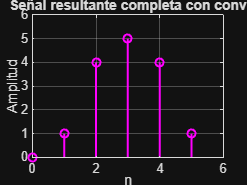


% Comparar con la convolución manual
figure;
y_conv = conv(x2, h2);
stem(0:length(y_conv)-1, y_conv, 'm', 'LineWidth', 1.5);
xlim([0 length(conv(x2,h2))]);
ylim([0 max(conv(x2,h2))+1]);
title('Señal resultante completa con conv');
xlabel('n');
ylabel('Amplitud');
grid on;


%valores de y2(señal convolucionada)
disp('Valores de la señal convolucionada');

Valores de la señal convolucionada


for n = 1:longitud_y2
    disp("valor" + " " + n + ": " + y2(n))
end

valor 1: 0
valor 2: 1
valor 3: 4
valor 4: 5
valor 5: 4
valor 6: 1



 
clear;

## Conclusión

La convolución es importante dentro el análisis de señales ya que con ellas podemos verificar comportamientos necesarios para la comprobación de un sistema lineal e invariante en el tiempo(LTI), donde su aplicación en nuestra carrera forma parte fundamental para un amplio análisis de un sistema ya que las convoluciones son aplicables en modelos mátematicos, CPU entre otras ejemplos como se mencionó anterioremente.

Asi que a grandes rasgos La operación de convolución de tiempo discreta se define de tal manera que realiza esta función para señales y sistemas de tiempo discretos de longitud infinita, por eso mismo su análisis en mathlab es con stem, que sirve para graficar funciones discretas.

## Referencias

Libretexts. (2022, 1 noviembre). *4.3: Convolución de tiempo discreta*. LibreTexts Español. [https://espanol.libretexts.org/Ingenieria/Se%C3%B1ales_y_Sistemas_(Baraniuk_et_al.)/04%3A_An%C3%A1lisis_de_dominio_de_tiempo_de_sistemas_discretos_de_tiempo/4.03%3A_Convoluci%C3%B3n_de_Tiempo_Discreta](https://espanol.libretexts.org/Ingenieria/Se%C3%B1ales_y_Sistemas_(Baraniuk_et_al.)/04%3A_An%C3%A1lisis_de_dominio_de_tiempo_de_sistemas_discretos_de_tiempo/4.03%3A_Convoluci%C3%B3n_de_Tiempo_Discreta) 

Carakenio. (2023, 22 septiembre). *La función Impulso Unitario*. Dademuchconnection. [https://dademuchconnection.wordpress.com/2020/09/11/la-funcion-impulso-unitario/](https://dademuchconnection.wordpress.com/2020/09/11/la-funcion-impulso-unitario/) 